[fn dname] = uigetfile();


[d,time,fs] = loadPclampData([dname fn]);


dp = d(:)-mean(d(:));
d_filt = lowpass(dp(:),10,fs);

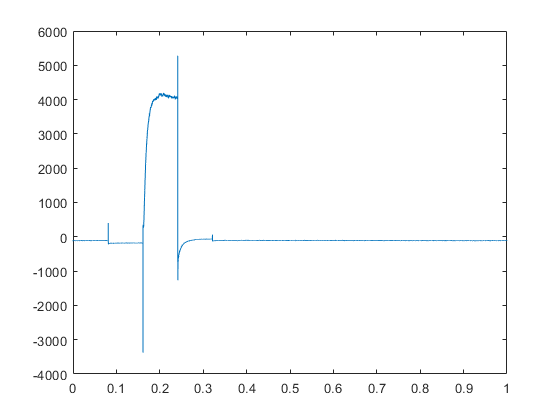

Error using plot
Vectors must be the same length.


figure; plot(time(1:20000),dp(1:20000));
hold on; plot(time,d_filt(1:20000))

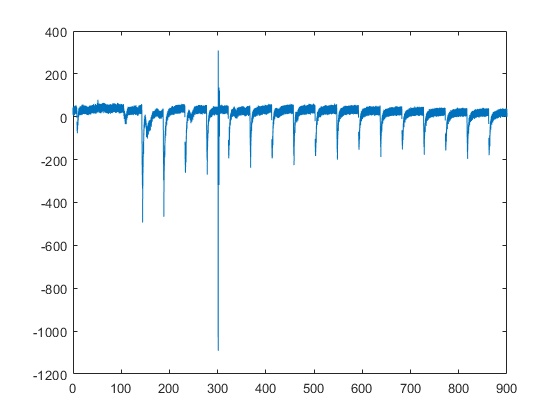

%clean up trace
dc = NaN(size(d,1),500);
dc(:,1:size(d,2)) = d;
dc(time > 0.08 & time < 0.35,:) = NaN;
t = size(dc(:),1);
tp = [0:t-1]/fs;
figure; plot(tp,dc(:))


%%reshape
%drs = reshape(dc(:),[],10)
%dc = fillmissing(dc(:),'linear');
%hold on; plot(tp,lowpass(dc(:),.01,fs));
%xlim([0 1000]);


temp = dc(:);
dnew = [];
for i = 1:20
    [0+(i-1)*45 (i*45)];
    dnew(:,i) = temp(tp> 0+(i-1)*45 & tp <= (i*45));
end


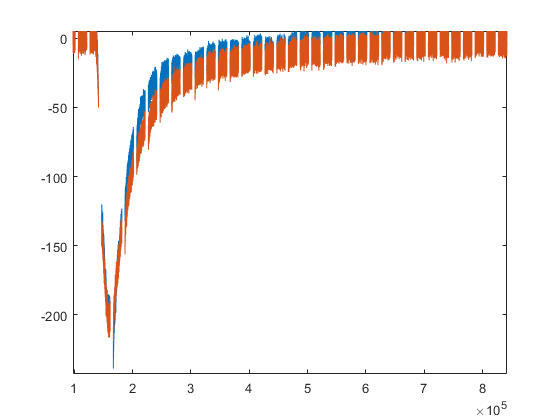

figure;
bl = mean(dnew(:,9:11),2);
drug = mean(dnew(:,[18:20]),2);

figure;
plot((bl - mean(bl(1:20))));
hold on;
plot((drug - mean(drug(1:20)))*1.2);

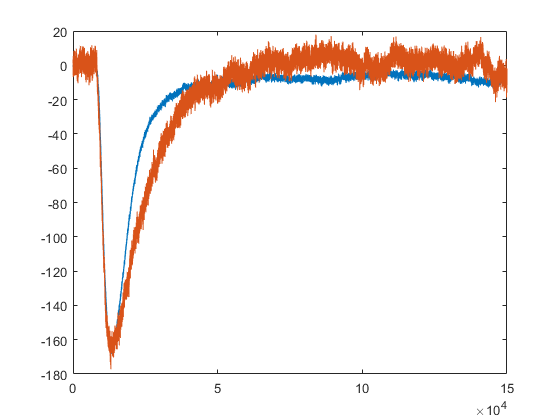

figure;
bl = mean(d(:,1:10),2);
drug = mean(d(:,17:24),2);

figure;
plot((bl - mean(bl(1:20))));
hold on;
plot((drug - mean(drug(1:20)))*3);